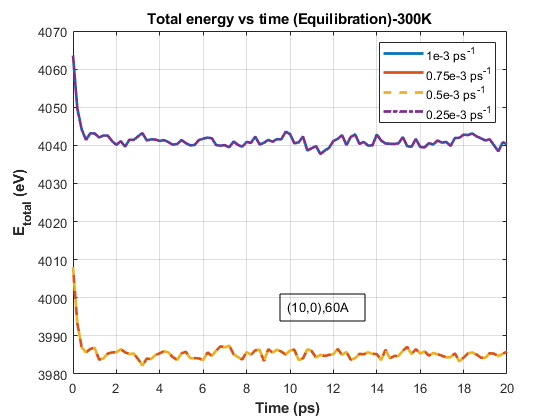

%%%%% ..a......
clc
clear all
close all

%%% fig 1:  Equilibration--time,etotal,pe,temp,pzz
%%%%% fig2:  deformation---time,etotal,pe,temp,strain,pzz


%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.e3.Equi.txt','rt');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.e3.Deform.txt','rt');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.75.Equi.txt','rt');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.75.Deform.txt','rt');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.5.Equi.txt','rt');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.5.Deform.txt','rt');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.25.Equi.txt','rt');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.300K.25.Deform.txt','rt');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));

Equ300K=EquCNT1001;

fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);

figure(1)  %%% equilibtration...
plot(EquCNT1001(:,1),EquCNT1001(:,2),"LineWidth",2); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,2),"LineWidth",2); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,2),'--',"LineWidth",2); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,2),'-.',"LineWidth",2); 

title('Total energy vs time (Equilibration)-300K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress vs Strain  SWCNT (20,0),60A,300K.jpg')

grid on
hold off

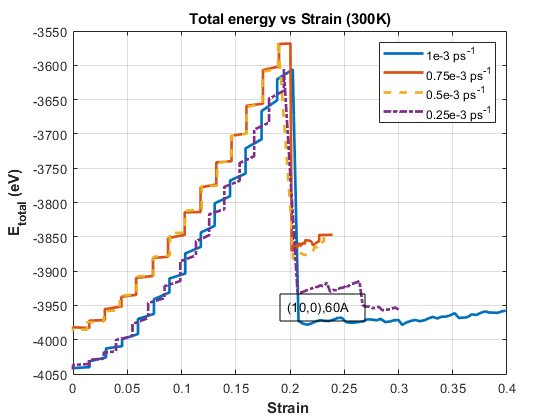


figure(2);   %deformation.........
plot(DefCNT1001(:,5),DefCNT1001(:,2),"LineWidth",2); 
hold on
plot(DefCNT10075(:,5),DefCNT10075(:,2),"LineWidth",2); 
hold on
plot(DefCNT1005(:,5),DefCNT1005(:,2),'--',"LineWidth",2); 
hold on
plot(DefCNT10025(:,5),DefCNT10025(:,2),'-.',"LineWidth",2); 
title('Total energy vs Strain (300K)')
xlabel('Strain ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress vs Strain  SWCNT (20,0),60A,300K.jpg')

hold off



%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.1.Equi.txt','rt');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.1.Deform.txt','rt');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.75.Equi.txt','rt');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.75.Deform.txt','rt');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.5.Equi.txt','rt');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.5.Deform.txt','rt');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.25.Equi.txt','rt');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.800K.25.Deform.txt','rt');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));

Equ800K=EquCNT1001

Equ800K = 	1.0e+04 *

         0    0.3972    0.4030    0.0800    0.3690
    0.0000    0.3932    0.3980    0.0668    0.2201
    0.0000    0.3915    0.3973    0.0798    0.1676
    0.0001    0.3909    0.3970    0.0839   -1.3518
    0.0001    0.3914    0.3969    0.0765    1.0127
    0.0001    0.3911    0.3971    0.0831   -2.7717
    0.0001    0.3907    0.3966    0.0811   -4.0190
    0.0001    0.3907    0.3967    0.0825    2.8523
    0.0002    0.3910    0.3967    0.0781   -0.1191
    0.0002    0.3911    0.3969    0.0793    1.5120


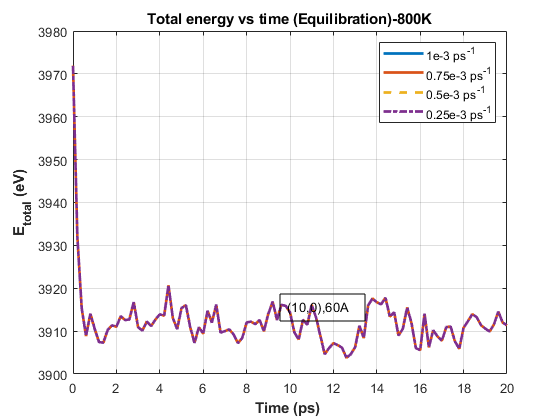


fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);

figure(3)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,2),"LineWidth",2); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,2),"LineWidth",2); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,2),'--',"LineWidth",2); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,2),'-.',"LineWidth",2); 
title('Total energy vs time (Equilibration)-800K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress vs Strain  SWCNT (20,0),60A,300K.jpg')

hold off

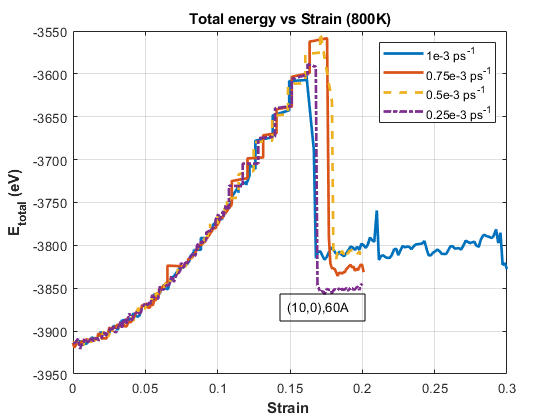


figure(4);   %deformation
plot(DefCNT1001(:,5),DefCNT1001(:,2),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT10075(:,5),DefCNT10075(:,2),"LineWidth",2);
hold on
plot(DefCNT1005(:,5),DefCNT1005(:,2),'--',"LineWidth",2);
hold on
plot(DefCNT10025(:,5),DefCNT10025(:,2),'-.',"LineWidth",2);

title('Total energy vs Strain (800K)')
xlabel('Strain ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress vs Strain  SWCNT (20,0),60A,300K.jpg')

hold off




%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.1.Equi.txt','rt');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.1.Deform.txt','rt');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.75.Equi.txt','rt');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.75.Deform.txt','rt');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.5.Equi.txt','rt');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.5.Deform.txt','rt');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.25.Equi.txt','rt');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.1600K.25.Deform.txt','rt');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));

Equ1600K=EquCNT1001

Equ1600K = 	1.0e+04 *

         0    0.3914    0.4030    0.1600   -1.2750
    0.0000    0.3834    0.3932    0.1360    0.8805
    0.0000    0.3797    0.3914    0.1608   -0.2175
    0.0001    0.3782    0.3903    0.1670   -3.3926
    0.0001    0.3796    0.3908    0.1547    1.0174
    0.0001    0.3792    0.3912    0.1654   -1.6924
    0.0001    0.3786    0.3905    0.1641   -5.6365
    0.0001    0.3799    0.3905    0.1466    3.9336
    0.0002    0.3790    0.3902    0.1548    0.4609
    0.0002    0.3784    0.3897    0.1564    1.5858


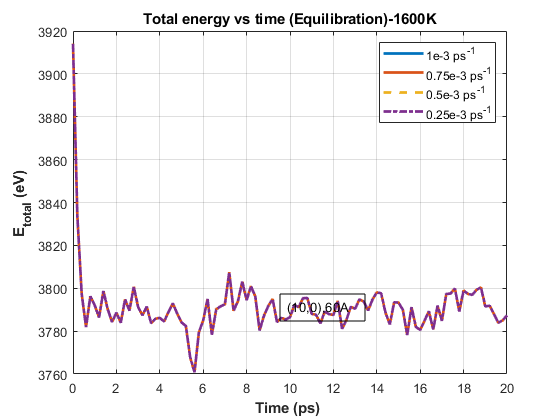


fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);

figure(5)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,2),"LineWidth",2); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,2),"LineWidth",2); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,2),'--',"LineWidth",2); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,2),'-.',"LineWidth",2); 
title('Total energy vs time (Equilibration)-1600K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress vs Strain  SWCNT (20,0),60A,300K.jpg')

hold off

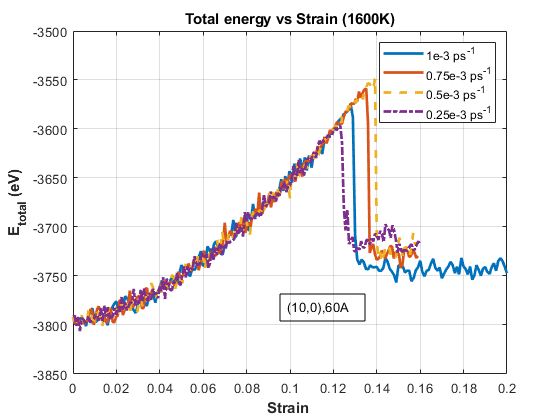


figure(6);   %deformation
plot(DefCNT1001(:,5),DefCNT1001(:,2),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT10075(:,5),DefCNT10075(:,2),"LineWidth",2);
hold on
plot(DefCNT1005(:,5),DefCNT1005(:,2),'--',"LineWidth",2); 
hold on
plot(DefCNT10025(:,5),DefCNT10025(:,2),'-.',"LineWidth",2); 

title('Total energy vs Strain (1600K)')
xlabel('Strain ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress vs Strain  SWCNT (20,0),60A,300K.jpg')

hold off

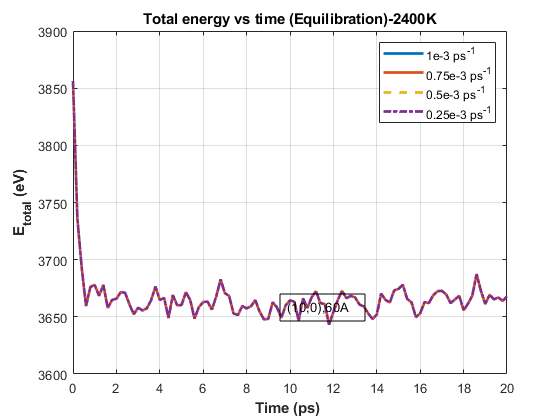




%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K
CNT100Equ1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.1.Equi.txt','rt');
CNT100Def1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.1.Deform.txt','rt');
CNT100Equ75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.75.Equi.txt','rt');
CNT100Def75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.75.Deform.txt','rt');
CNT100Equ5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.5.Equi.txt','rt');
CNT100Def5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.5.Deform.txt','rt');
CNT100Equ25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.25.Equi.txt','rt');
CNT100Def25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\CNT.10.0.60.2400K.25.Deform.txt','rt');

EquCNT1001 = cell2mat(textscan(CNT100Equ1,'%f%f%f%f%f','headerlines',1));
DefCNT1001 =cell2mat(textscan(CNT100Def1,'%f%f%f%f%f%f','headerlines',1));
EquCNT10075 = cell2mat(textscan(CNT100Equ75,'%f%f%f%f%f','headerlines',1));
DefCNT10075 =cell2mat(textscan(CNT100Def75,'%f%f%f%f%f%f','headerlines',1));
EquCNT1005 = cell2mat(textscan(CNT100Equ5,'%f%f%f%f%f','headerlines',1));
DefCNT1005 =cell2mat(textscan(CNT100Def5,'%f%f%f%f%f%f','headerlines',1));
EquCNT10025 = cell2mat(textscan(CNT100Equ25,'%f%f%f%f%f','headerlines',1));
DefCNT10025 =cell2mat(textscan(CNT100Def25,'%f%f%f%f%f%f','headerlines',1));

Equ2400K=EquCNT1001;

fclose(CNT100Equ1);
fclose(CNT100Def1);
fclose(CNT100Equ75);
fclose(CNT100Def75);
fclose(CNT100Equ5);
fclose(CNT100Def5);
fclose(CNT100Equ25);
fclose(CNT100Def25);

figure(7)  %%% equilibtration...stress vs time
plot(EquCNT1001(:,1),EquCNT1001(:,2),"LineWidth",2); 
hold on
plot(EquCNT10075(:,1),EquCNT10075(:,2),"LineWidth",2); 
hold on
plot(EquCNT1005(:,1),EquCNT1005(:,2),'--',"LineWidth",2); 
hold on
plot(EquCNT10025(:,1),EquCNT10025(:,2),'-.',"LineWidth",2); 

title('Total energy vs time (Equilibration)-2400K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress vs Strain  SWCNT (20,0),60A,300K.jpg')

hold off

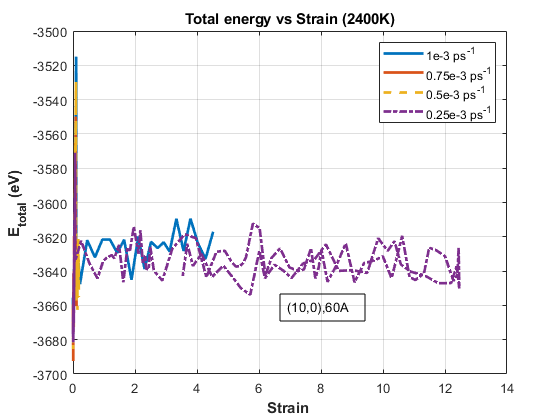


figure(8);   %deformation
plot(DefCNT1001(:,5),DefCNT1001(:,2),"LineWidth",2); % strain vs stress
hold on
plot(DefCNT10075(:,5),DefCNT10075(:,2),"LineWidth",2);
hold on
plot(DefCNT1005(:,5),DefCNT1005(:,2),'--',"LineWidth",2); 
hold on
plot(DefCNT10025(:,5),DefCNT10025(:,2),'-.',"LineWidth",2); 
title('Total energy vs Strain (2400K)')
xlabel('Strain ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
annotation('textbox', [0.5, 0.2, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress vs Strain  SWCNT (20,0),60A,300K.jpg')

hold off

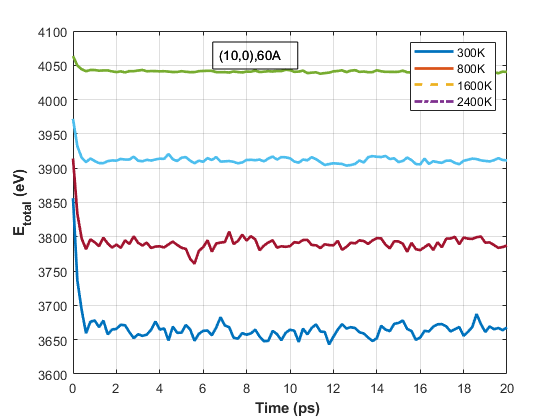

%%%%%%%%%% Energy vs time all
%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz
figure(9)  %%% equilibtration...stress vs time
plot(Equ300K(:,1),Equ300K(:,2),"LineWidth",2); hold on
plot(Equ800K(:,1),Equ800K(:,2),"LineWidth",2); hold on
plot(Equ1600K(:,1),Equ1600K(:,2),"LineWidth",2); hold on
plot(Equ2400K(:,1),Equ2400K(:,2),"LineWidth",2); 

%title('Total energy vs time (Equilibration)-2400K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('E_{total} (eV)',"FontWeight","bold")
legend('300K','800K','1600K','2400K')
grid on
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
%saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Equilibration_100.jpg','Delimiter','tab')